clear;clc;

img = imread('lena.bmp')

img = 256×256 uint8 矩阵
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   138   133   134   134   136   132   130   130   131   134   128   127   131   128   128   130   130   128   136   138   142   146   150   150   149   148   143   132   119   111    88    78    65    61    60    66    70    69    73    74    75    74    73    76    73    73    76    73    76    76
   133   133   133   130   134   133   128   125   129   128   128   125  

[height, width] = size(img)

height = 256

width = 256

subsampledImage = zeros(height,width)

subsampledImage =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0 


samplerate = 2

samplerate = 2

heightindex = 1:samplerate:height

heightindex =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51    53    55    57    59    61    63    65    67    69    71    73    75    77    79    81    83    85    87    89    91    93    95    97    99


widthindex = 1:samplerate:width

widthindex =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51    53    55    57    59    61    63    65    67    69    71    73    75    77    79    81    83    85    87    89    91    93    95    97    99


subsampledheight = ceil(height/samplerate)

subsampledheight = 128

subsampledwidth = ceil(width/samplerate)

subsampledwidth = 128


for i = 1:subsampledheight
    subsampledImage(i,1:subsampledwidth) = img(heightindex(i),widthindex)
end

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
     0     0     0     0     0     0     0     0     0     0     0     0     0 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage =    137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93    96    91    98    97   107   100    97   103    99   104    98   102   101   100   103   101   102   101   105   105
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92    93    90    99    99   104   101    97   102    98   104   100   104   101   102   102   100   101   100   104   103
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88    93    93    92    95    99    97    99    98   100    98    98   101   101   103    98   103    98   100   102    96
   131   130   132   128   130   133   128   128   131   140   147   145   144 

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

subsampledImage = 256×256
   137   133   138   134   132   129   132   129   130   138   142   151   149   143   119    90    64    61    71    73    78    76    76    78    78    74    79    83    83    93
   138   134   136   130   131   128   131   128   130   136   142   150   149   143   119    88    65    60    70    73    75    73    73    76    76    74    79    84    85    92
   129   130   133   132   128   130   129   126   126   137   146   148   149   140   116    87    61    56    64    67    72    67    71    72    71    74    79    80    84    88
   131   130   132   128   130   133   128   128   131   140   147   145   144   139   112    85    63    57    59    67    70    74    77    67    67    68    82    81    86    89
   129   130   130   130   127   130   125   128   138   145   144   143   142   131   111    87    59    53    57    70    74    72    71    70    68    67    77    81    83    89
   130   129   131   133   133   126   127   133   141   140   142   

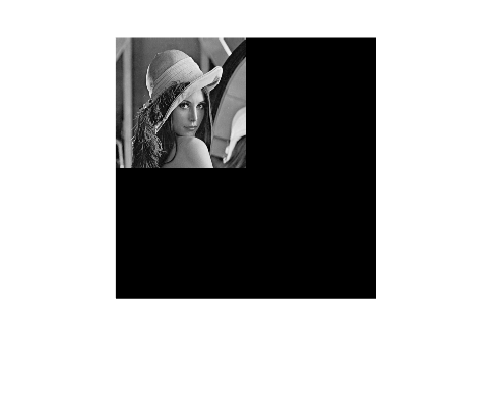


imshow(subsampledImage, [])